# **CA#2 **

## **Name: Sogol Goodarzi **

## **SID: 810198467**

# **Part 1 **

## **1.2)**

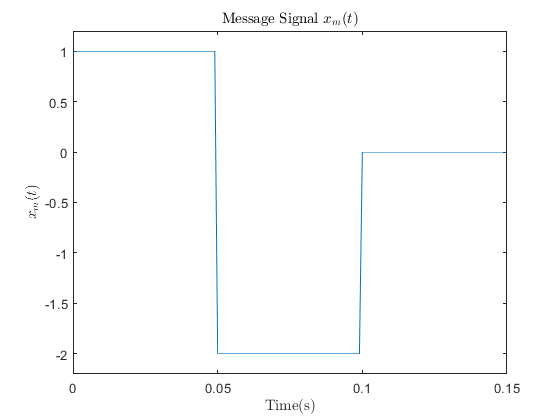

Ac=1;
fc=250;
mu=0.85;
t0=0.15;
fs=4*fc;
t=0:1/fs:t0;
xm(find(t==0 | t<t0/3))=1;
xm(find(t>t0/3 & t<2*t0/3))=-2;
xm(find(t>2*t0/3))=0;
xm_norm=xm/max(abs(xm));
plot(t,xm);
ylim([-2.2 1.2]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$x_m(t)$','Interpreter','latex')
title ('Message Signal $x_m(t)$','Interpreter','latex')

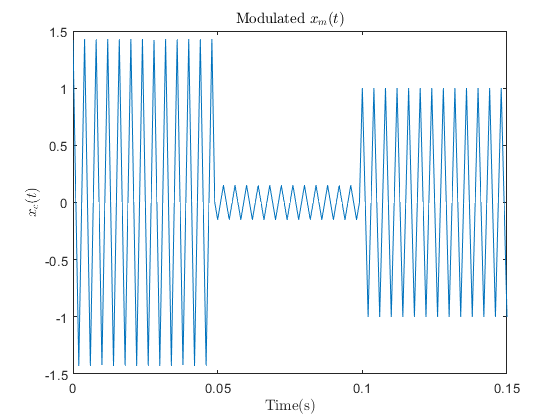

xm_mod=AM_mod(xm_norm,t,Ac,mu,fc);
plot(t,xm_mod)
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$x_c(t)$','Interpreter','latex')
title ('Modulated $x_m(t)$','Interpreter','latex')

## 1.3) 

### Message Signal Spectrum:

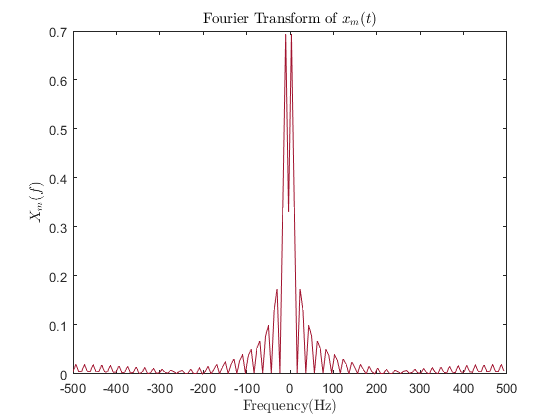

Xm=fftshift(fft(xm));
N=length(xm);
f=-fs/2:fs/N:fs/2-fs/N;
plot(f,abs(real(Xm))/N,'color','#A2142F');
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_m(f)$','Interpreter','latex')
title ('Fourier Transform of $x_m(t)$','Interpreter','latex')

### Modulated Signal Spectrum:

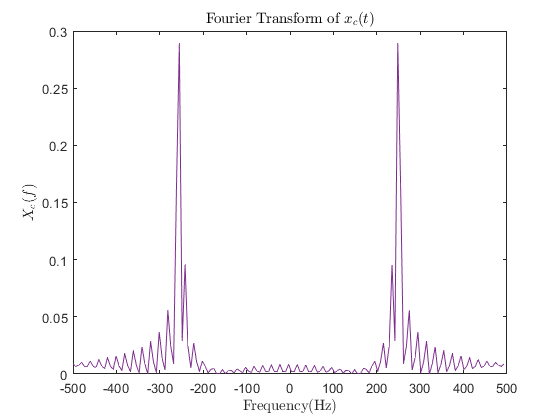

Xc=fftshift(fft(xm_mod));
N=length(xm_mod);
f=-fs/2:fs/N:fs/2-fs/N;
plot(f,abs(real(Xc))/N,'color','#7E2F8E');
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$X_c(f)$','Interpreter','latex')
title ('Fourier Transform of $x_c(t)$','Interpreter','latex')

## 1.4)

### Power of $x_c \left(t\right)$

Sx=sum(xm.^2)/(t0*fs);
ST=Ac^2/2*(1+mu^2.*Sx);
fprintf('Power of the modulated signal is %0.5f',ST);

Power of the modulated signal is 1.10208

### Modulation Efficiency

ME=((mu^2*Sx)/(1+mu^2.*Sx));
fprintf('Modulation Efficiency is %0.5f',ME);

Modulation Efficiency is 0.54631

## 1.5)

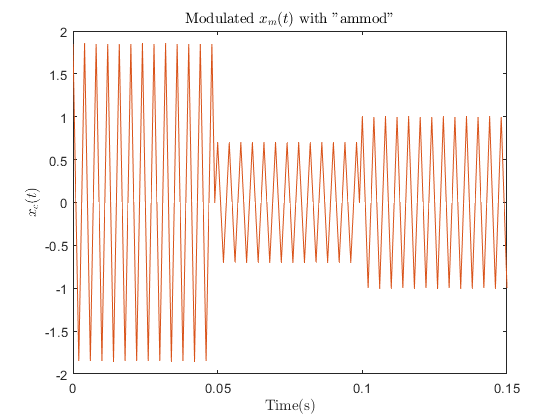

y_AM=ammod(mu*Ac*xm,fc,fs,0,Ac);
plot(t,y_AM,'color','#D95319');
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$x_c(t)$','Interpreter','latex')
title ('Modulated $x_m(t)$ with "ammod"','Interpreter','latex')

# **Part 2 **

## **2.1)**

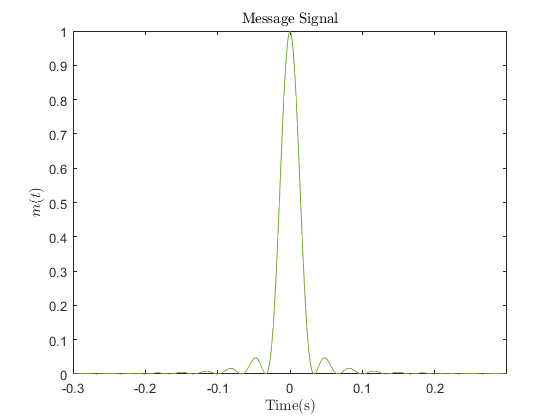

fs=600; Ts=1/fs;
t=-5:1/fs:5;
N=length(t);
f=-fs/2:fs/N:fs/2-1/N;
m=(sinc(30*t)).^2;
plot(t,m,'color','#77AC30');
xlim([-0.3 0.3]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m(t)$','Interpreter','latex')
title ('Message Signal','Interpreter','latex')

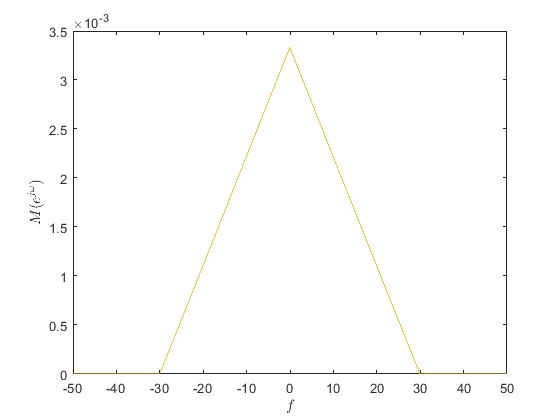

M_dis=fftshift(fft(m));
w=2*pi*f./fs;
plot(f,abs(real(M_dis)/N),'color','#EDB120');
xlim([-50 50]);
xlabel ('$f$','Interpreter','latex')
ylabel ('$M(e^{j\omega})$','Interpreter','latex')

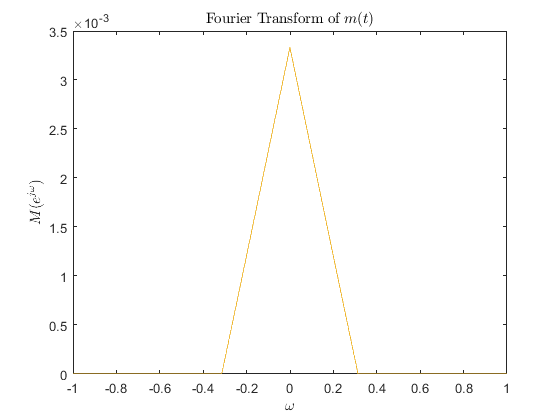

plot(w,abs(real(M_dis)/N),'color','#EDB120');
xlim([-1 1]);
xlabel ('$\omega$','Interpreter','latex')
ylabel ('$M(e^{j\omega})$','Interpreter','latex')
title ('Fourier Transform of $m(t)$','Interpreter','latex')

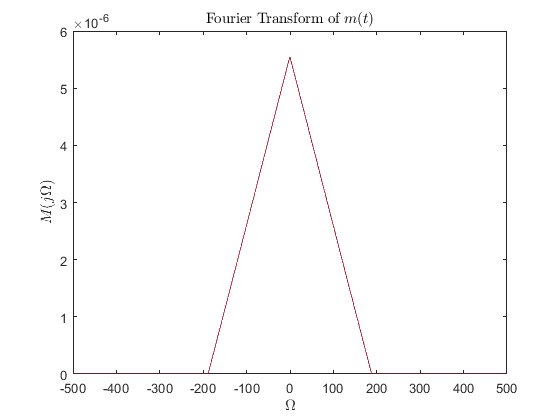

M_con=Ts*M_dis;
Omega=w/Ts;
plot(Omega,abs(real(M_con)/N),'color','#A2142F');
xlim([-500 500]);
xlabel ('$\Omega$','Interpreter','latex')
ylabel ('$M(j\Omega)$','Interpreter','latex')
title ('Fourier Transform of $m(t)$','Interpreter','latex')

## 2.3)

### 
$$f_c =50\mathrm{Hz}$$


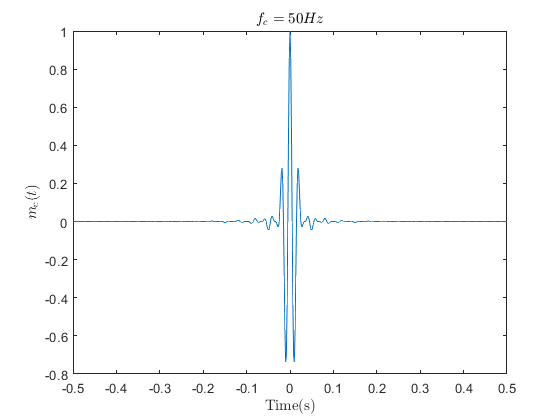

Ac=1;
fc1=50;
xc_dsb1=DSB_mod(m,t,Ac,fc1);
plot(t,xc_dsb1);
xlim([-0.5 0.5]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m_c(t)$','Interpreter','latex')
title ('$f_c=50Hz$','Interpreter','latex')

### 
$$f_c =200\mathrm{Hz}$$


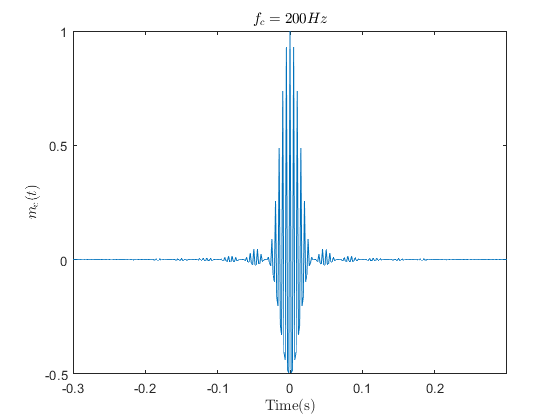

fc2=200;
xc_dsb2=DSB_mod(m,t,Ac,fc2);
plot(t,xc_dsb2);
xlim([-0.3 0.3]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m_c(t)$','Interpreter','latex')
title ('$f_c=200Hz$','Interpreter','latex')

### 
$$f_c =600\mathrm{Hz}$$


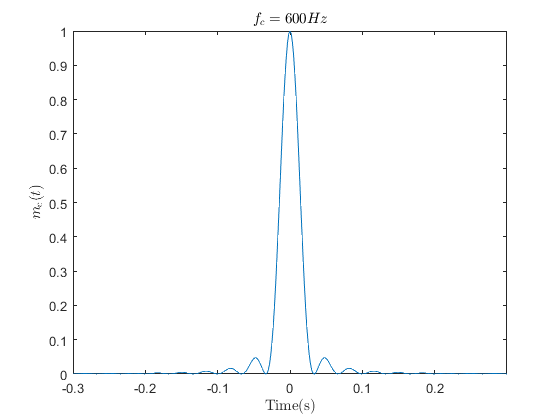

fc3=600;
xc_dsb3=DSB_mod(m,t,Ac,fc3);
plot(t,xc_dsb3);
xlim([-0.3 0.3]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m_c(t)$','Interpreter','latex')
title ('$f_c=600Hz$','Interpreter','latex')

### 
$$f_c =1200\mathrm{Hz}$$


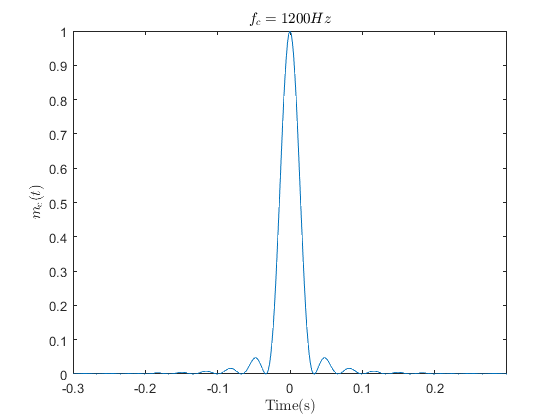

fc4=1200;
xc_dsb4=DSB_mod(m,t,Ac,fc4);
plot(t,xc_dsb4);
xlim([-0.3 0.3]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m_c(t)$','Interpreter','latex')
title ('$f_c=1200Hz$','Interpreter','latex')

## 2.4)

### $f_c =100\mathrm{Hz}$ ,  $A_c =1$

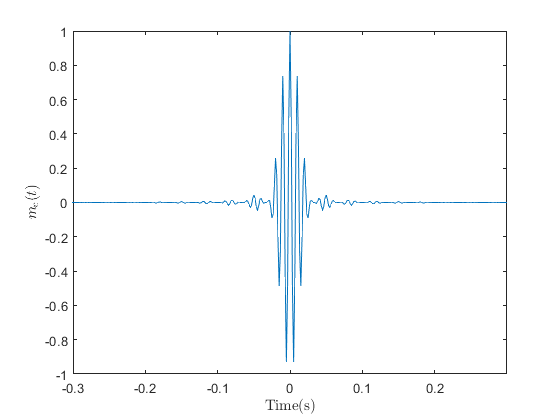

fc=100;
Ac=1;
N=length(m);
f=-fs/2:fs/N:fs/2-fs/N;
mc_dsb=DSB_mod(m,t,Ac,fc);
plot(t,mc_dsb)
xlim([-0.3 0.3]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m_c(t)$','Interpreter','latex')

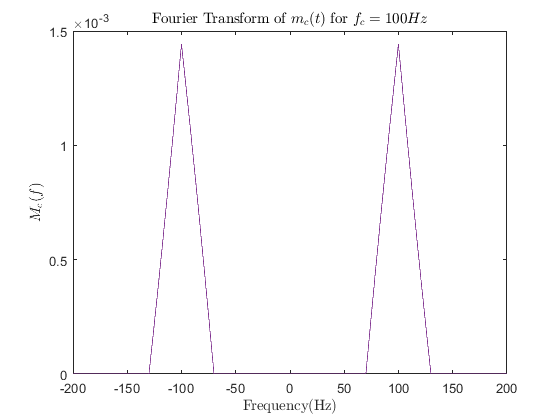

Mc_dsb=fftshift(fft(mc_dsb)/N);
plot(f,abs(real(Mc_dsb)),'color','#7E2F8E');
xlim([-200 200]);
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$M_c(f)$','Interpreter','latex')
title ('Fourier Transform of $m_c(t)$ for $f_c=100Hz$','Interpreter','latex')

## 2.6)

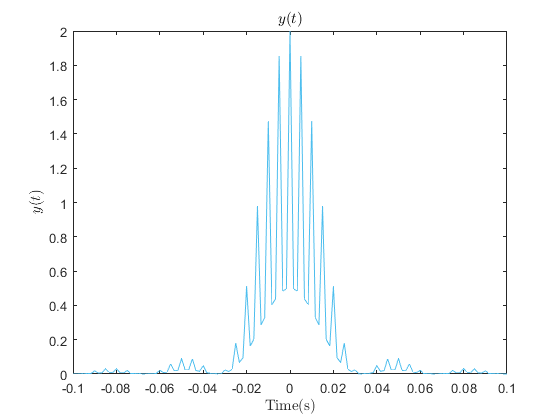

y=2*Ac*mc_dsb.*cos(2*pi*fc*t);
plot(t,y,'color','#4DBEEE');
xlim([-0.1 0.1]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$y(t)$','Interpreter','latex')
title ('$y(t)$','Interpreter','latex')

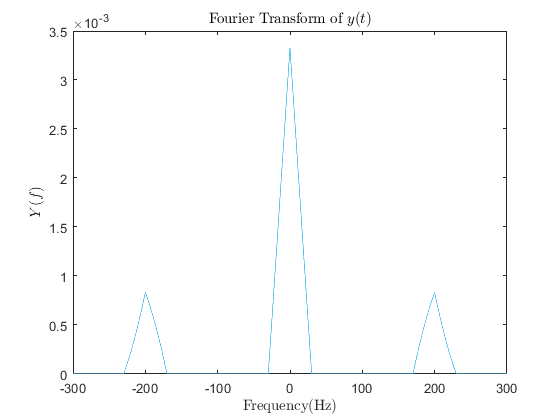

Y=fftshift(fft(y));
plot(f,abs(real(Y)/N),'color','#4DBEEE');
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$Y(f)$','Interpreter','latex')
title ('Fourier Transform of $y(t)$','Interpreter','latex')

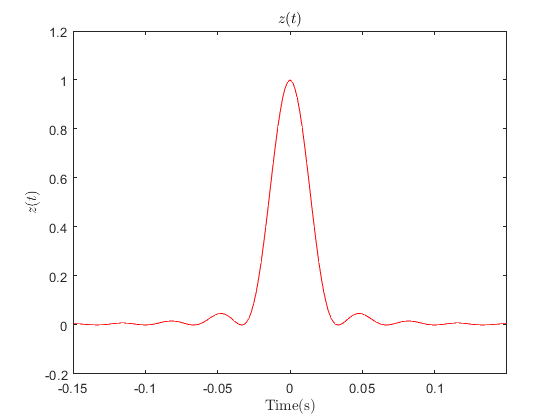

mc_demod=DSB_demod(mc_dsb,t,Ac,fc,fc/2);
plot(t,mc_demod,'r');
xlim([-0.15 0.15]);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$z(t)$','Interpreter','latex')
title ('$z(t)$','Interpreter','latex')

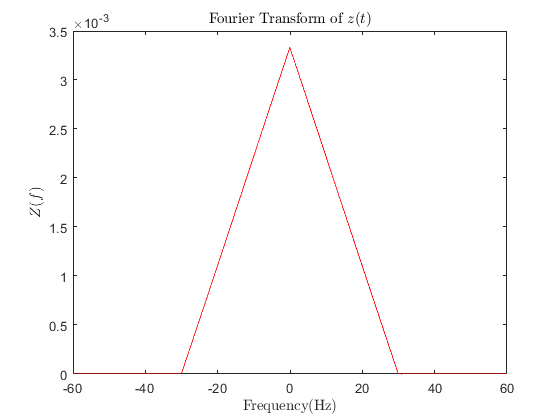

Z=fftshift(fft(mc_demod));
plot(f,abs(real(Z)/N),'r');
xlim([-60 60]);
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$Z(f)$','Interpreter','latex')
title ('Fourier Transform of $z(t)$','Interpreter','latex')

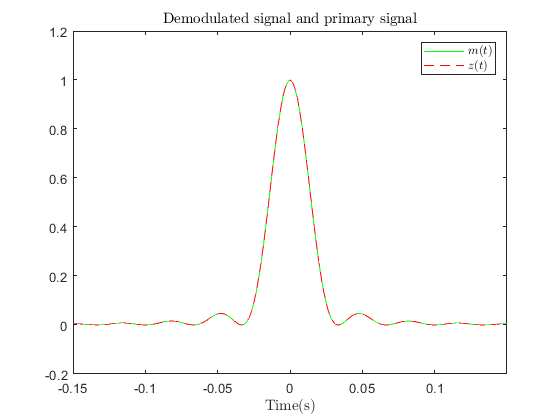

plot(t,m,'g',t,mc_demod,'r--')
xlim([-0.15 0.15]);
xlabel ('Time(s)','Interpreter','latex')
title ('Demodulated signal and primary signal','Interpreter','latex')
legend('$m(t)$','$z(t)$','Interpreter','latex');

error=immse(mc_demod,m);
fprintf('The mean-squared error is %0.11f', error);

The mean-squared error is 0.00000000025

## 2.7)

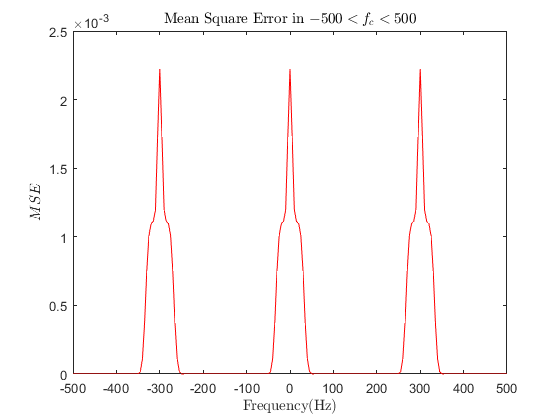

fc=-500:5:500;
for i=1:1:length(fc)
    mc_dsbmod=DSB_mod(m,t,Ac,fc(i));
    z_=DSB_demod(mc_dsbmod,t,Ac,fc(i),50);
    Error(i)=immse(z_,m);
end
plot(fc,Error,'r');
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$MSE$','Interpreter','latex')
title ('Mean Square Error in $-500<f_c<500$','Interpreter','latex')

## 2.8)

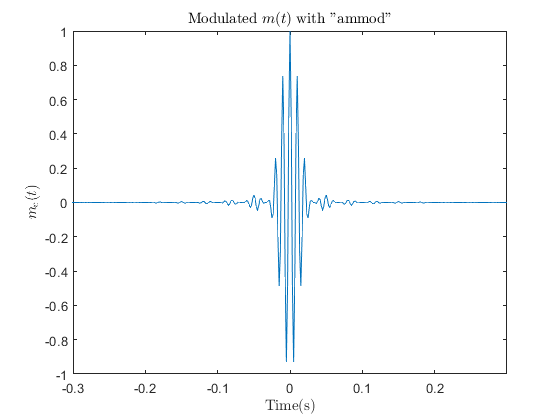

fc=100; 
m_mod=ammod(m,fc,fs);
plot(t,m_mod);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m_c(t)$','Interpreter','latex')
title ('Modulated $m(t)$ with "ammod"','Interpreter','latex')
xlim([-0.3 0.3]);

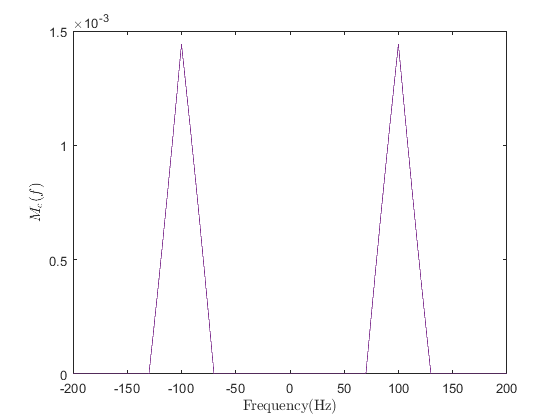

M_mod=fftshift(fft(m_mod));
plot(f,abs(real(M_mod)/N),'color','#7E2F8E');
xlim([-200 200]);
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$M_c(f)$','Interpreter','latex')

## 2.9)

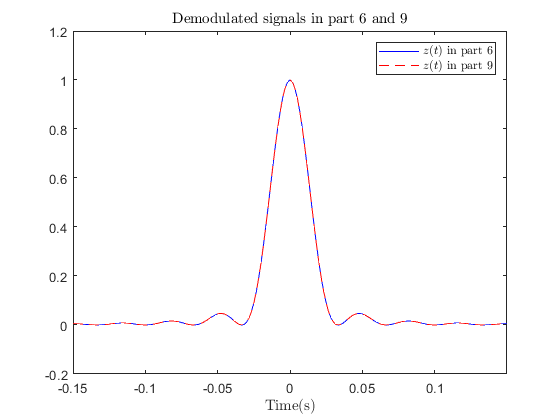

fc=100;
z=amdemod(m_mod,fc,fs);
plot(t,mc_demod,'b',t,z,'r--');
xlim([-0.15 0.15]);
xlabel ('Time(s)','Interpreter','latex')
title ('Demodulated signals in part 6 and 9','Interpreter','latex')
legend('$z(t)$ in part 6','$z(t)$ in part 9','Interpreter','latex');

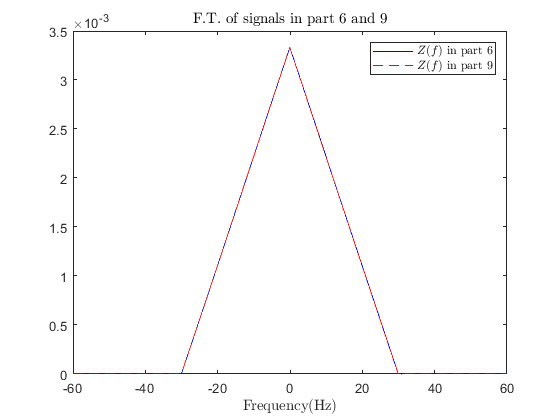

Z9=fftshift(fft(z));
plot(f,abs(real(Z))/N,'b',f,abs(real(Z9))/N,'r--');
xlim([-60 60]);
xlabel ('Frequency(Hz)','Interpreter','latex')
title ('F.T. of signals in part 6 and 9','Interpreter','latex')
legend('$Z(f)$ in part 6','$Z(f)$ in part 9','Interpreter','latex');

## 2.10)

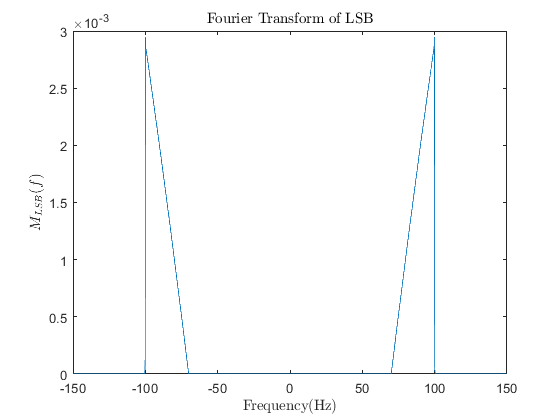

fc=100;
mc_LSB=ssbmod(m,fc,fs);
Mc_LSB=fftshift(fft(mc_LSB));
plot(f,abs(real(Mc_LSB))/N);
xlim([-150 150]);
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$M_{LSB}(f)$','Interpreter','latex')
title ('Fourier Transform of LSB','Interpreter','latex')

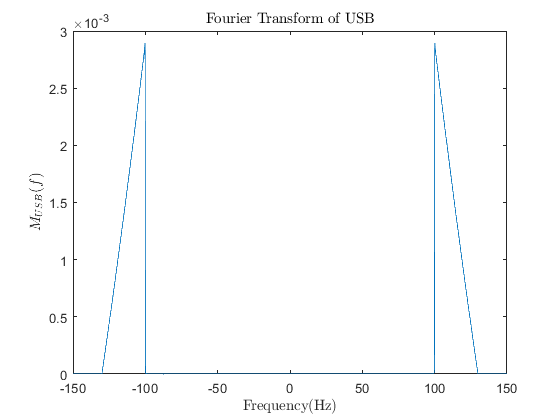

mc_USB=ssbmod(m,fc,fs,0,'upper');
Mc_USB=fftshift(fft(mc_USB));
plot(f,abs(real(Mc_USB))/N);
xlim([-150 150]);
xlabel ('Frequency(Hz)','Interpreter','latex')
ylabel ('$M_{USB}(f)$','Interpreter','latex')
title ('Fourier Transform of USB','Interpreter','latex')

# **Part 3 **

## **3.2)**

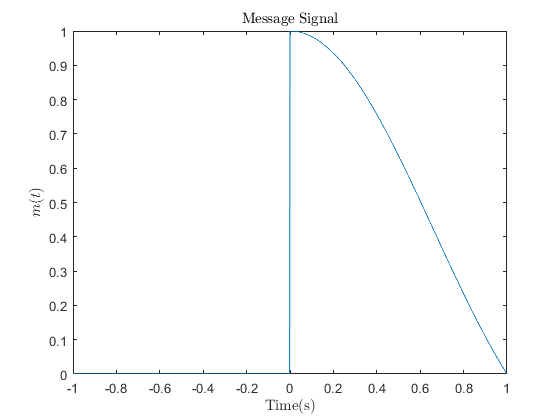

fs=600;
t_=-1:1/fs:1;
for i=1:1:length(t_)
    if (t_(i)==0 || t_(i)==1)
        m_(i)=sinc(t_(i));
    else if (t_(i)>0 && t_(i)<1)
            m_(i)=sinc(t_(i));
    else 
        m_(i)=0;
    end
    end
end
plot(t_,m_);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m(t)$','Interpreter','latex')
title ('Message Signal','Interpreter','latex')

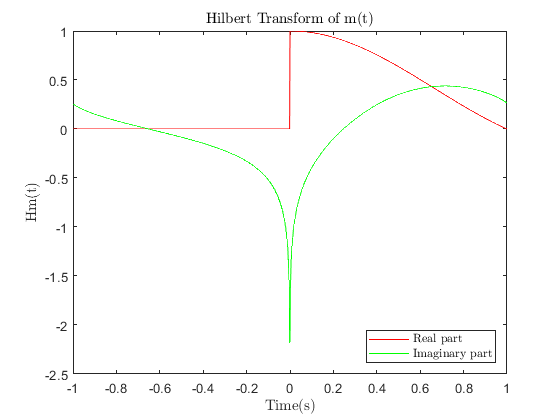

H_m=hilbert(m_);
plot(t_,real(H_m),'r',t_,imag(H_m),'g');
legend('Real part','Imaginary part','Interpreter','latex','Location','southeast');
xlabel ('Time(s)','Interpreter','latex')
ylabel ('H{m(t)}','Interpreter','latex')
title ('Hilbert Transform of m(t)','Interpreter','latex')

## 3.3)

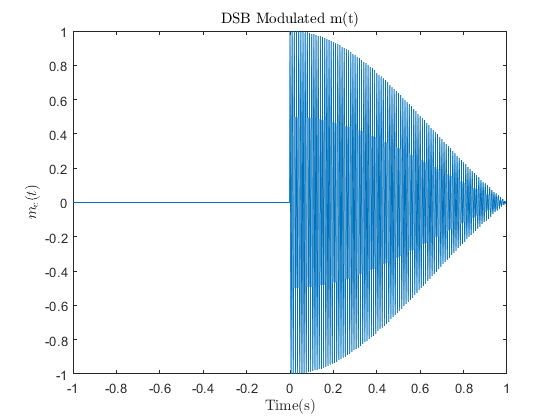

fc=100; Ac=1;
mc=DSB_mod(m_,t_,Ac,fc);
plot(t_,mc);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m_c(t)$','Interpreter','latex')
title ('DSB Modulated m(t)','Interpreter','latex')

## 3.4)

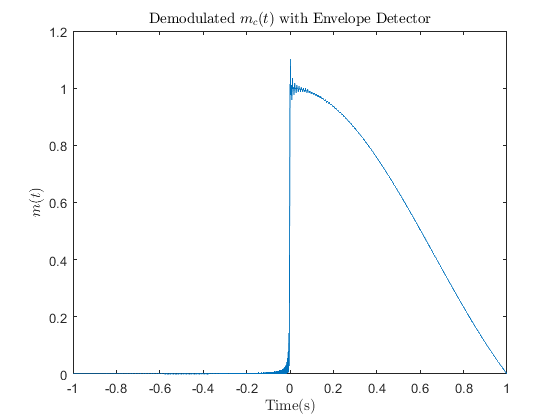

H_mc=hilbert(mc);
A=abs(H_mc);
plot(t_,A);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m(t)$','Interpreter','latex')
title ('Demodulated $m_c(t)$ with Envelope Detector','Interpreter','latex')

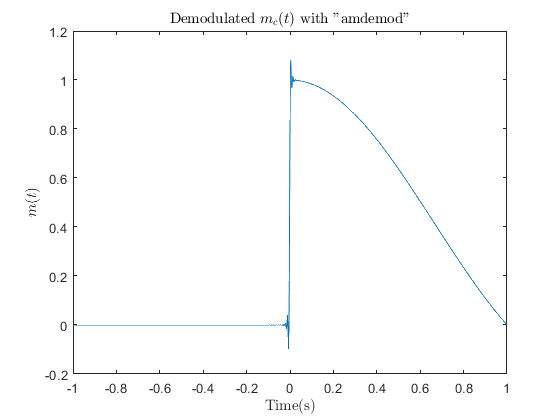

plot(t_,amdemod(mc,fc,fs));
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m(t)$','Interpreter','latex')
title ('Demodulated $m_c(t)$ with "amdemod"','Interpreter','latex')

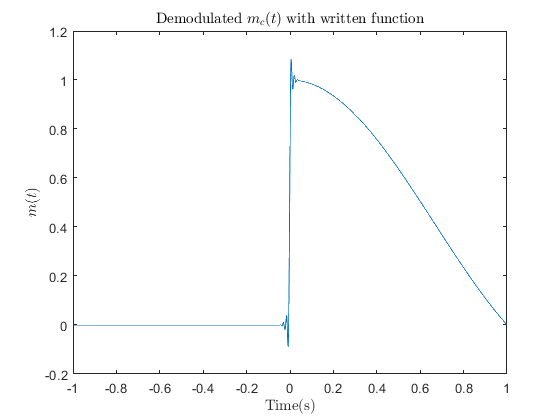

mc_demod=DSB_demod(mc,t_,Ac,fc,fc/2);
plot(t_,mc_demod);
xlabel ('Time(s)','Interpreter','latex')
ylabel ('$m(t)$','Interpreter','latex')
title ('Demodulated $m_c(t)$ with written function','Interpreter','latex')

# **Functions **

## **1.1)**

function [xc] = AM_mod(xm,t,Ac,mu,fc)
xc=Ac.*(1+mu.*xm).*cos(2.*pi.*fc.*t);
end

## **2.2)**

function [xc] = DSB_mod(m,t,Ac,fc)
xc=Ac*m.*cos(2*pi*fc*t);
end

## 2.5)

function [xm] = DSB_demod(xc,t,Ac,fc,fpass)
y=2*Ac*xc.*cos(2*pi*fc*t);
xm=lowpass(y,fpass,600);
end